# **ANALYSIS OF THE VALENTIA DATA**

**1) download the IAEA WISER data for Valentia GNIP station**

**2) import to MATLAB**

clear all
clf
% first manually delete tab References
v = 'valentia.xlsx';

Using readtable function:

s = readtable (v); % reading data from the specific Data File

%%%%% to delete this? : d = datenum(s.Date, 'yyyy-mm-dd'); % converting date to machine readable serial code

The data is not chronological: ordering data by date.

%%% sort the data by date: %%%
allDates=s.Date(:); % gives all dates in one cell
A = datetime(allDates,'Format','yyyy-MM-dd'); % formats 'allDates' cell to an array datetime values

[sortDates,originalIndex]=sort(A); %sorts A array (708x1 - includes only dates) into ascending order.
                                  %originalIndex gives the original index or s table

sortedS=s(originalIndex,:); %print s table with originalIndex, which gives data in ascending date

Saving measurements for H2, H3 and O18 as variables:

% convenient labelling of variables
H2 = sortedS. H2;
H3 = sortedS.H3;
O18 = sortedS.O18;

H2 variance with respect to time:

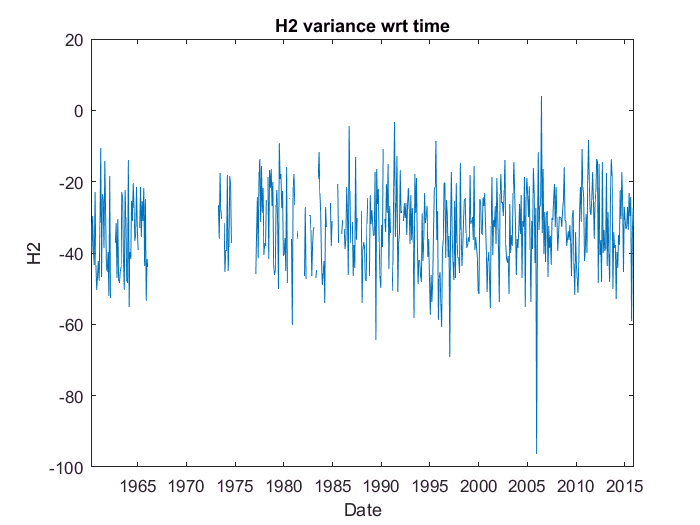

figure (1)
plot (sortDates, H2);
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('H2 variance wrt time')

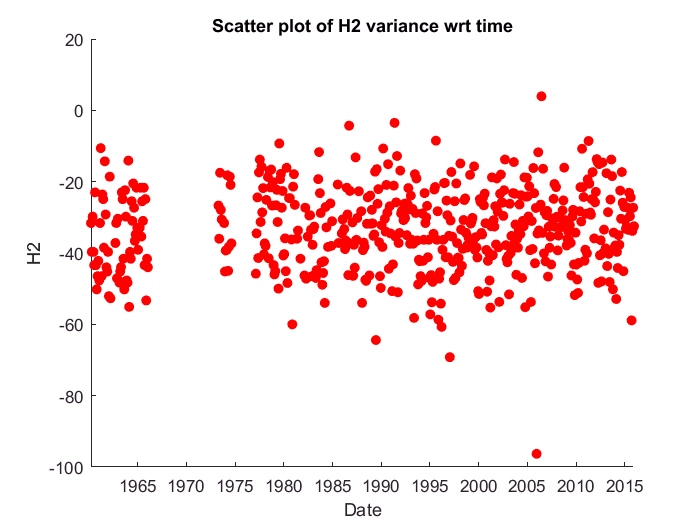


figure (2)
scatter (sortDates, H2, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('Scatter plot of H2 variance wrt time')

H3 variance with respect to time:

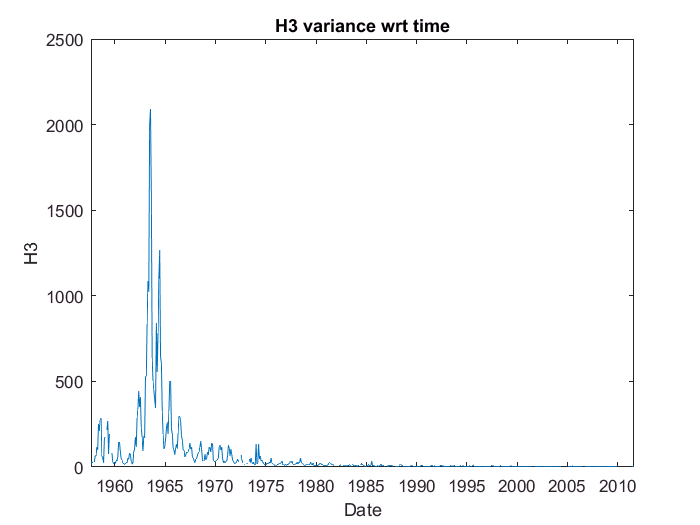

figure (3)
plot (sortDates, H3);
datetick('x','yyyy','keeplimits')
xlabel ('Date');
ylabel ('H3');
title ('H3 variance wrt time')

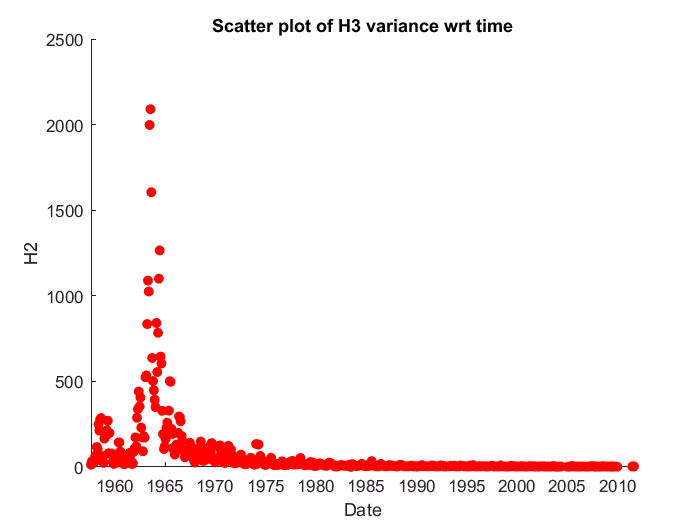


figure (4)
scatter (sortDates, H3, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('Scatter plot of H3 variance wrt time')

O18 variance with respect to time:

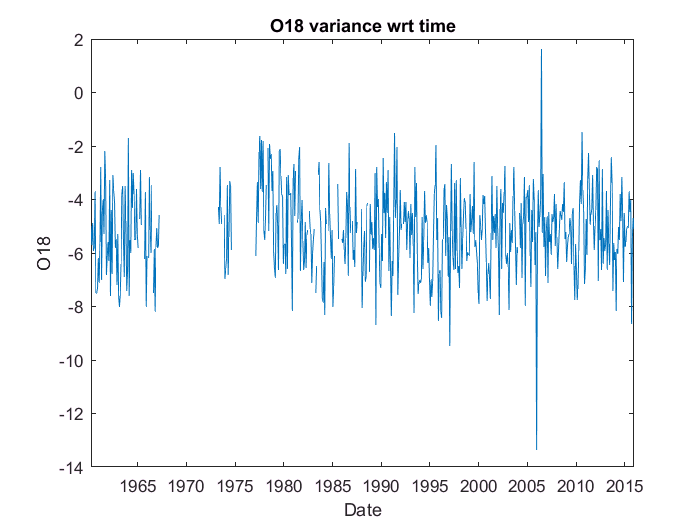

figure (5)
plot (sortDates, O18);
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('O18');
title ('O18 variance wrt time')

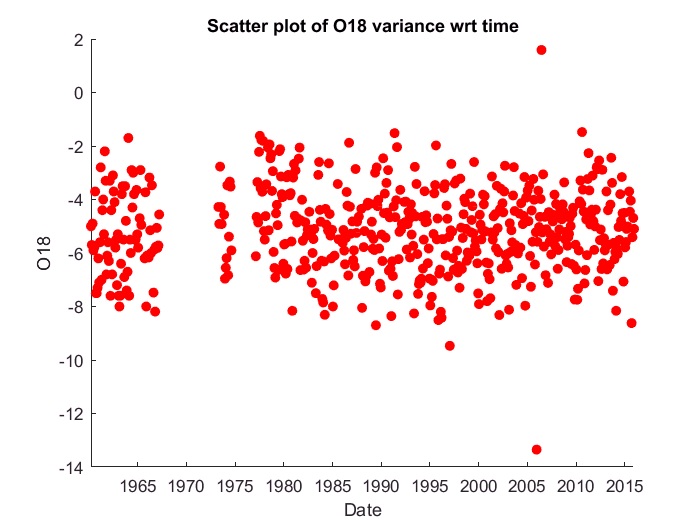


figure (6)
scatter (sortDates, O18, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('O18');
title ('Scatter plot of O18 variance wrt time')

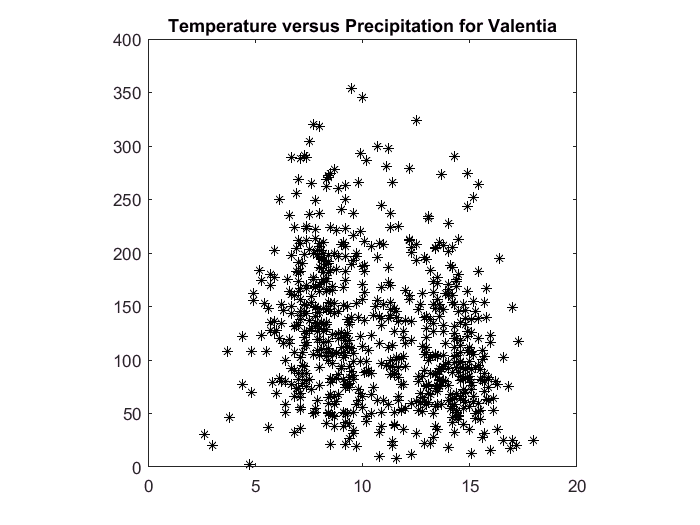

% Investigating temperature dependence of precipitation (scatter plot) for Valentia data

precip = sortedS.Precipitation;
temp = sortedS.AirTemperature;

figure(5)
scatter (temp, precip, '*k')
axis square
box on
title ('Temperature versus Precipitation for Valentia')

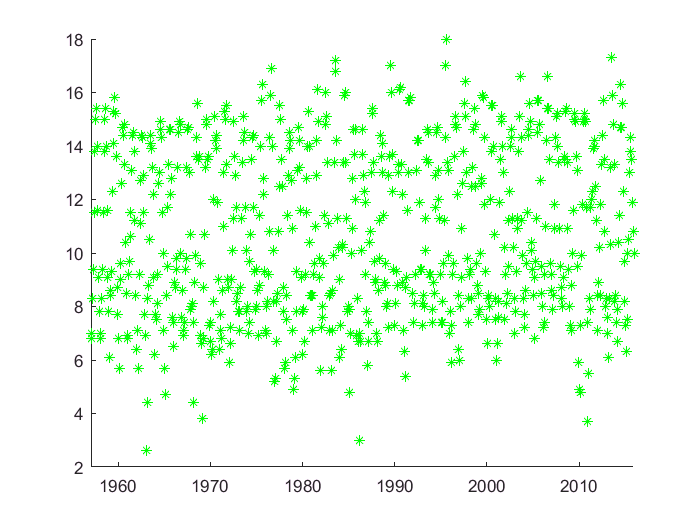

% Investigating temperature dependence on time for Valentia data

figure(6)
scatter (sortDates, temp, '*g')

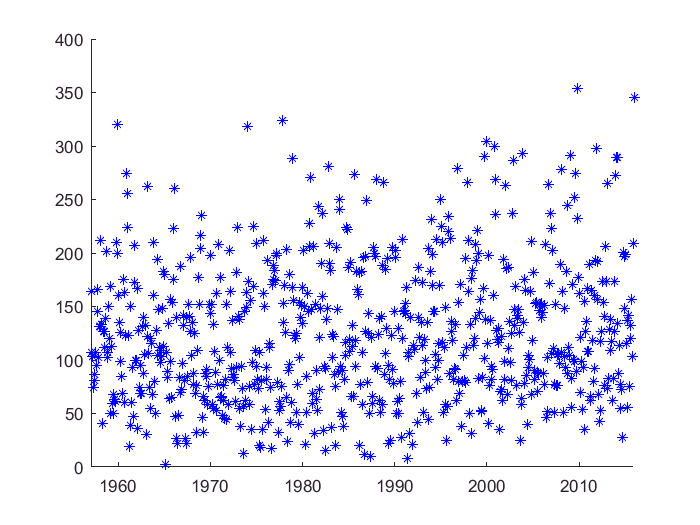

% Investigating precipitation dependence on time for Valentia data

figure(7)
scatter (sortDates, precip, '*b')

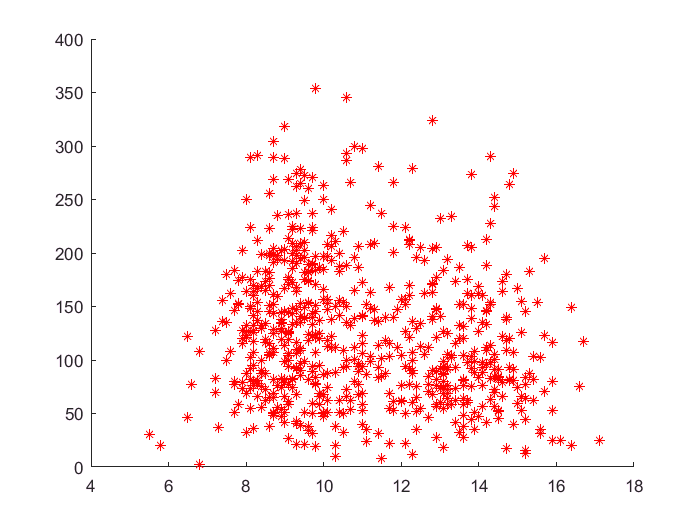

% Investigating precipitation dependence on vapour pressure
vap = sortedS.VapourPressure;

figure (8)
scatter (vap, precip, '*r')

% Delta D versus precipitation rate per day, histogram, fitted normal distribution

According to the  reference *G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017 *on page 3707, the abundance of deuterium is measured with the following formula:


$$\delta D=\left(\frac{R_{\mathrm{sample}} }{R_{\mathrm{VSMOW}} }-1\right)\cdot 1000\text{ }‰$$


where:

$R_{\mathrm{sample}}$ is the ratio of deuterium to the common, stable isotope of hydrogen in the samples considered,

 $R_{\mathrm{VSMOW}}$ is the same ratio but for a reference sample with the isotopic composition of the Vienna standard mean ocean water.

$\delta D$ is included in the downloaded IAEA WISER data.

begin = datenum(sortedS.BeginOfPeriod, 'yyyy-mm-dd'); % converting the date (Begin of Period) to machine readable serial code
finish = datenum(sortedS.EndOfPeriod, 'yyyy-mm-dd');  % converting the date (End of Period) to machine readable serial code

days_in_month = finish - begin; % number of days in each month (for each measurement)
precip_rate = sortedS.Precipitation./days_in_month; % precipitation rate per day

H2 = sortedS. H2; % delta D

% LITERALLY NO IDEA PLS FROM HERE DOWN

b = [precip_rate, H2]

b =     5.4667       NaN
    3.9630       NaN
    3.4333       NaN
    2.5517       NaN
    2.8667       NaN
    2.7931       NaN
    3.5667       NaN
    3.1667       NaN
    5.7241       NaN
    4.8333       NaN


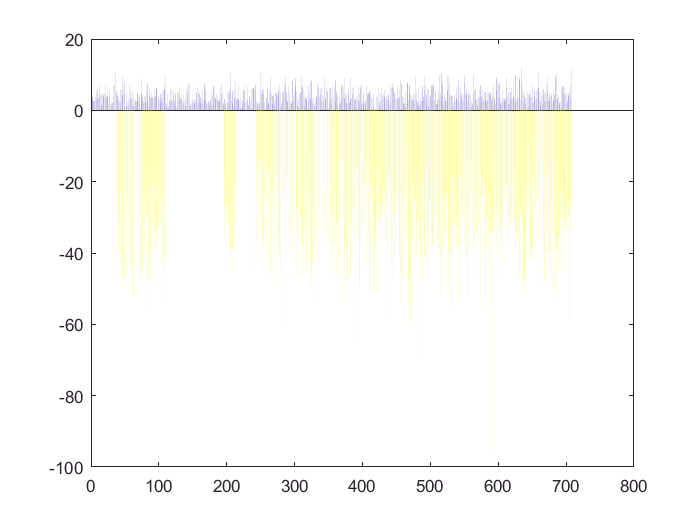


bar (b)

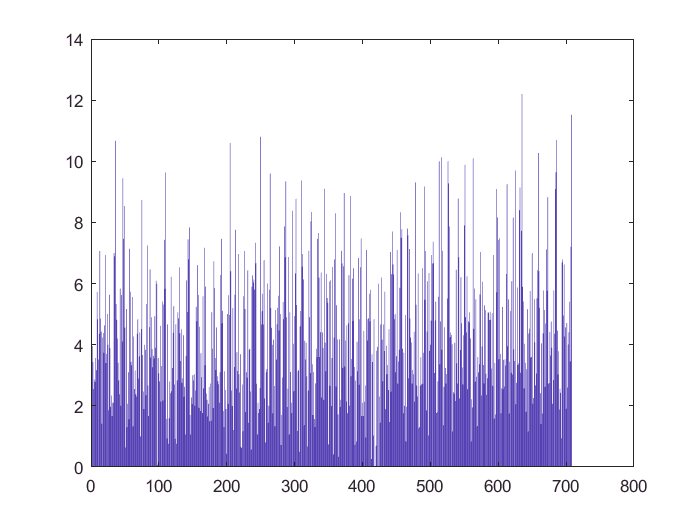


bar (precip_rate)

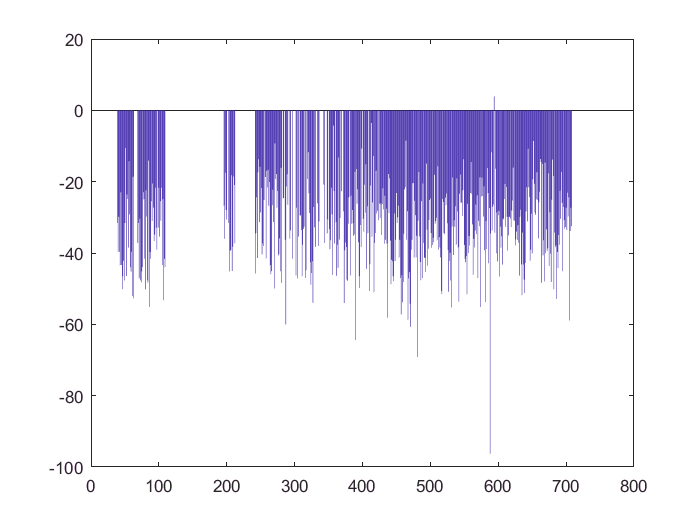

bar (H2)